load("Internet.mat")

MB = internet(:,1)

MB =    163
   170
   169
   173
   160
   168
   163
   173
   168
   165


n = length(MB)

n = 95

%% Question 1

x = MB;
a = 0;
b = 1024;
y = a + b*x;

qvar_factor = n/(n-1);
qvar_x = var(x)*qvar_factor

qvar_x = 68.4047

qvar_y = var(y)*qvar_factor

qvar_y = 7.1728e+07

qstd_x = sqrt(qvar_x)

qstd_x = 8.2707

qstd_y = sqrt(qvar_y)

qstd_y = 8.4692e+03

checks1 = [mean(y) == a+b*mean(x), median(y) == a+b*median(x), ...
    qvar_y == power(b,2)*qvar_x, qstd_y == abs(b)*qstd_x]

checks1 = 1×4 logical array
   1   1   1   1


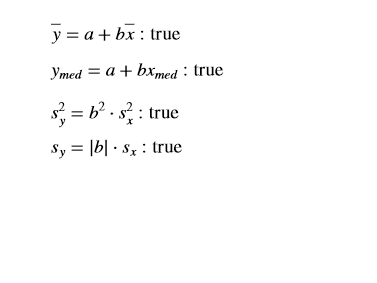

expressions1 = ["\bar{y} = a+b \bar{x}", "y_{med} = a+b x_{med}", ...
    "s_{y}^{2} = b^{2} \cdot s_{x}^{2}", "s_{y} = \left| b \right| \cdot s_{x}"];
expressions1 = arrayfun(@(expr, val) sprintf("$%s : \\mathrm{%s}$", expr, val), ...
    expressions1, string(checks1), UniformOutput=false);

clf;
axis off;
for i = 1:numel(expressions1)
    text(0, 1-(i-1)/6, expressions1(i), Interpreter="latex", FontSize=14, ...
        Units="normalized", HorizontalAlignment="left", VerticalAlignment="top")
end

%% Question 2

x = MB;
y = (x-mean(x))/std(x);

fprintf("mean = %.4f", mean(y))

mean = -0.0000

fprintf("s^2 = %.4f", var(y))

s^2 = 1.0000

fprintf("s = %.4f", std(y))

s = 1.0000

e = 1e-15; % Error to use when comparing floating point numbers
checks2 = [abs(mean(y)-0) < e, abs(var(y)-0) < e, abs(std(y)-0) < e];

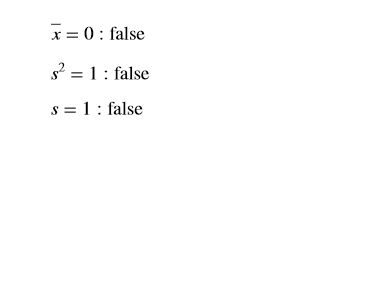

expressions2 = ["\bar{x} = 0", "s^{2} = 1", "s = 1"];
expressions2 = arrayfun(@(expr, val) sprintf("$%s : \\mathrm{%s}$", expr, val), ...
    expressions2, string(checks2), UniformOutput=false);

clf;
axis off;
for i = 1:numel(expressions2)
    text(0, 1-(i-1)/6, expressions2(i), Interpreter="latex", FontSize=14, ...
        Units="normalized", HorizontalAlignment="left", VerticalAlignment="top")
end